Compae how two arms (tapered vs non-tapered) reach the same point

### Test 1: Horizontal reaching under load test from Oliver-Butler et al 2017

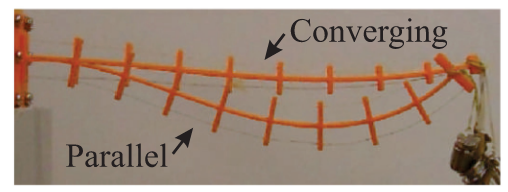

One crucial note on this test is that the actuation pressures are not the same between the converging and parallel arms. Instead, "the manipulators were placed under a 0.9-N tip load and **actuated back to the zero position as closely as possible**". Thus, the comparison must be between the arms under "optimal control inputs".

N_seg = 10;
rho_base = 0.015;
rho_tip = 0.0025;
l_0 = 0.25;

arm_straight = ArmSeriesFactory.constant_2d_muscle_arm(N_seg, rho_base, l_0);
arm_straight.set_mechanics(GinaMuscleMechanics(l_0));
arm_straight.segments(1).g_0_o = eye(3);

arm_converging = ArmSeriesFactory.tapered_2d_muscle_arm(N_seg, rho_base, rho_tip, l_0);
arm_converging.set_mechanics(GinaMuscleMechanics(l_0));
arm_converging.segments(1).g_0_o = eye(3);

tic
arm_straight.solve_equilibrium_gina([0; 20], [0; -0.4; 0], "fast", true);

fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
   -0.0004   -0.0012   -0.0010   -0.0019   -0.0007   -0.0007   -0.0007    0.0003
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0313   -0.0227   -0.0141   -0.0060    0.0009    0.0052    0.0050    0.0032
  Columns 9 through 10
    0.0003    0.0002
   -0.0000   -0.0000
    0.0027    0.0009


toc

Elapsed time is 40.958501 seconds.


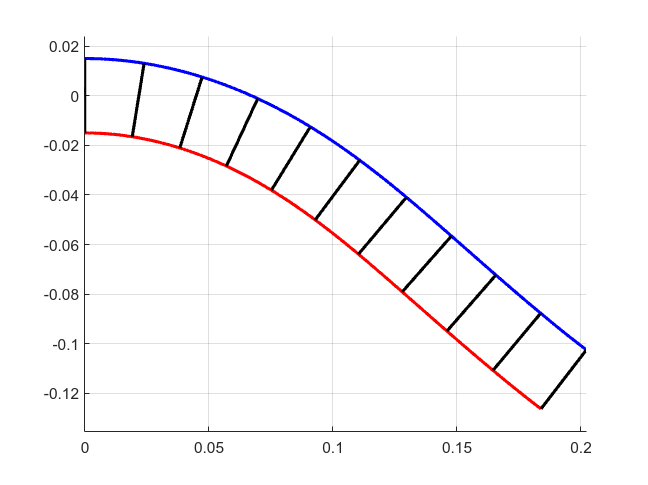

Plotter2D.plot_arm_series(arm_straight, axes(figure()));

g_target = Pose2.hat([l_0; 0; 0]);
Q = [0; -0.8; 0];
tic
[res_straight, p_straight] = evaluate_arm(arm_straight, {g_target}, Q);

fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
   -0.0017   -0.0014   -0.0011   -0.0008   -0.0006   -0.0003   -0.0001    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.1188   -0.0998   -0.0793   -0.0613   -0.0442   -0.0267   -0.0137   -0.0035
  Columns 9 through 10
    0.0001    0.0001
   -0.0000   -0.0000
    0.0054    0.0069
fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
   -0.0018   -0.0015   -0.0012   -0.0009   -0.0007   -0.0004   -0.0002   -0.0001
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.1262   -0.1058   -0.0876   -0.0675   -0.0515   -0.0364   -0.0206   -0.0098
  Columns 9 through 10
    0.0001    0.0001
   -0.0000   -0.0000
   -0.0008    0.0047
fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
   -0.0019   -0.0016   -0.0014   -0.0011   -0.0008   -0.0006   -0.0004   -0.0002
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -

toc
tic
[res_tapered, p_tapered] = evaluate_arm(arm_converging, {g_target}, Q);

fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
   -0.5379    0.2621    0.2621    0.2621    0.2621    0.2621    0.2621    0.2621
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
  Columns 9 through 10
    0.2621    0.2621
         0         0
         0         0
fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
   -0.0017   -0.0012   -0.0008   -0.0009   -0.0006   -0.0002   -0.0000    0.0001
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.1840   -0.1684   -0.1518   -0.1344   -0.1163   -0.0978   -0.0789   -0.0595
  Columns 9 through 10
    0.0001    0.0001
   -0.0000   -0.0000
   -0.0398   -0.0199
fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
   -0.0020   -0.0016   -0.0012   -0.0008   -0.0005   -0.0002   -0.0001    0.0001
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -

toc

arm_straight.solve_equilibrium_gina([0; 50], [0; -0.9; 0], "fast", true);

File: ArmSeries.m Line: 265 Column: 17
Invalid expression. When calling a function or indexing a variable, use parentheses.
Otherwise, check for mismatched delimiters.

Plotter2D.plot_arm_series(arm_straight, axes(figure()));

arm_converging.solve_equilibrium_gina(p_tapered, [0; -0.9; 0], "fast", true);

fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
   -0.0019   -0.0014   -0.0009   -0.0006   -0.0008   -0.0004   -0.0002   -0.0001
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.2072   -0.1896   -0.1709   -0.1512   -0.1308   -0.1098   -0.0885   -0.0667
  Columns 9 through 10
   -0.0001   -0.0001
   -0.0000   -0.0000
   -0.0446   -0.0223


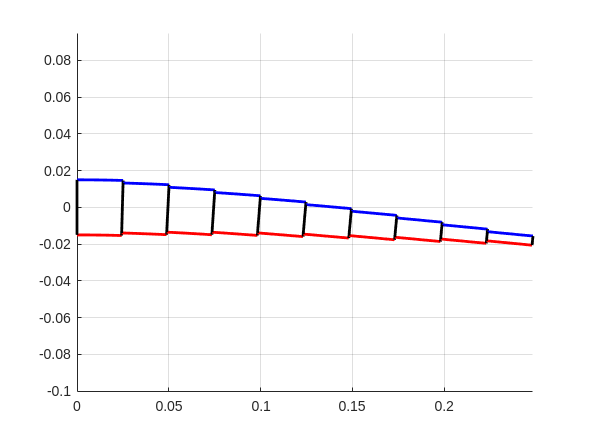

Plotter2D.plot_arm_series(arm_converging, axes(figure()));